ЛАБОРАТОРНА РОБОТА №4

з навчальної дисципліни «Математичне моделювання систем і процесів»

Виконав:

Студент 5 курсу

Групи ФФ-21мн

Бондар О.В.

Перевірив:

Гордійко Н.О.

Варіант №1 

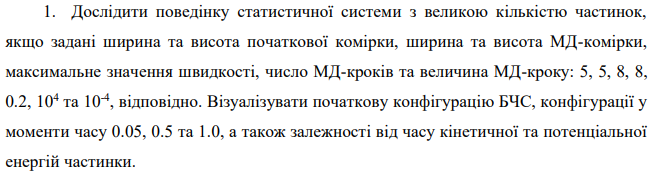

clearvars;
Nx=5;
Ny=5;
Lx=8;
Ly=8;

Vmax=0.2;
dt=10^(-4);
Ni=10^4;

metMD(Nx,Ny,Lx,Ly,Vmax,Ni,dt)

function metMD(Nx,Ny,Lx,Ly,Vmax,Ni,dt)
% Lx - ширина МД-комірки, Ly - висота МД-комірки
% N - число частинок системи
% Ni - число МД-кроків, dt - крок інтегрування рівнянь руху
% А - масив, який повертає функція init
N=Nx*Ny;
A=init(Lx,Ly,Nx,Ny,Vmax) 
md=MD(Lx,Ly,N,Ni,dt,A)

figure(1); plot(md(:,1,1),md(:,2,1),'o','LineWidth',2); axis([0 Lx 0 Ly]);
title('Початкова конфігурація статистичної системи'); xlabel('\itx'); ylabel("\ity");
figure(2); plot(md(:,1,501),md(:,2,501),'o','LineWidth',2); axis([0 Lx 0 Ly]);
title('Конфігурація статистичної системи у момент часу t=0.05'); xlabel('\itx'); ylabel("\ity");
figure(3); plot(md(:,1,5001),md(:,2,5001),'o','LineWidth',2); axis([0 Lx 0 Ly]);
title('Конфігурація статистичної системи у момент часу t=0.5'); xlabel('\itx'); ylabel("\ity");
figure(4); plot(md(:,1,10001),md(:,2,10001),'o','LineWidth',2); axis([0 Lx 0 Ly]);
title('Конфігурація статистичної системи у момент часу t=1'); xlabel('\itx'); ylabel("\ity");

for i=1:Ni+1
    N1(i)=0;
    tmp=md(:,1,i);
    for j=1:N
        if tmp(j)<=Lx/2
            N1(i)=N1(i)+1;
        end
    end
end

for i=1:Ni+1
    Sum=0;
    tmpVx=md(:,3,i); tmpVy=md(:,4,i);
    for j=1:N
        Sum=Sum+0.5*(tmpVx(j)^2+tmpVy(j)^2);
    end
    Ek(i)=Sum; Ep(i)=md(N,7,i);
end

i=1:Ni+1; figure(5); plot((i-1)*dt,Ek/N); title('Залежність кінетичної енергії частинки від часу'); xlabel('\itt'); ylabel("\itE-kinetic");
i=1:Ni+1; figure(6); plot((i-1)*dt,Ep/N); title('Залежність потенціальної енергії частинки від часу'); xlabel('\itt'); ylabel("\itE-potential");

end


function z=init(Lx,Ly,Nx,Ny,Vmax) 
% Функція, яка повертає початкову конфігурацію системи
% Lx - ширина МД-комірки, Ly - висота МД-комірки
% Nx - ширина початкової комірки, Ny - висота початкової комірки
% Vmах - максимальне значення швидкості
Posrow=Ly/(Ny+1); Poscol=Lx/(Nx+1);
N=Nx*Ny; % число частинок системи
i=1;
for Rows=1:Ny
    for Col=1:Nx
        x(i)=Poscol*Col/2; y(i)=Posrow*Rows; % задання початкових координат частинок
        % задання початкових швидкостей частинок
        Vx(i)=Vmax*(2*rand(1)-1); Vy(i)=Vmax*(2*rand(1)-1);
        i=i+1;
    end
end
Vxfull=mean(Vx); Vyfull=mean(Vy); % проекції швидкості центру мас системи
i=1:N;
Vx(i)=Vx(i)-Vxfull; Vy(i)=Vy(i)-Vyfull;
% повернення матриці, що містить початкові значення координат 
% та проекцій швидкостей частинок статистичної системи
z=cat(2,x',y',Vx',Vy');
end

function z=Acc(RV,Lx,Ly,N)
% Функція, що повертає миттєві прискорення кожної частинки системи
% та миттєве значення потенціальної енергії
% RV - матриця, яку повертає функція init
% Lx - ширина МД-комірки, Ly - висота МД-комірки
% N - число частинок системи
Ep=0;
for i=1:N
    Ax(i)=0; Ay(i)=0; Pe(i)=0;
end
for i=1:N-1
    for j=i+1:N
        Dx=RV(i,1)-RV(j,1);
        % перевірка граничних умов
        if abs(Dx)>Lx/2
            Dx=Dx-sign(Dx)*Lx;
        end
        Dy=RV(i,2)-RV(j,2);
        % перевірка граничних умов
        if abs(Dy)>Ly/2
            Dy=Dy-sign(Dy)*Ly;
        end
        Ax(i)=Ax(i)+Fx(Dx,Dy); % проекція прискорення на ось оХ
        Ax(j)=Ax(j)-Fx(Dx,Dy); % третій закон Ньютона
        Ay(i)=Ay(i)+Fy(Dx,Dy); % проекція прискорення на ось оУ
        Ay(j)=Ay(j)-Fy(Dx,Dy); % третій закон Ньютона
        r=(Dx^2+Dy^2).^0.5;
        Ep=Ep+4*(1/r.^12-1/r.^6); % потенціальна енергія
    end
end
Pe(N)=Ep;
z=cat(2,Ax',Ay',Pe');
end

function z1=Fx(x,y)
% Проекція сили, діючої на частинку, уздовж осі оХ
z1=-2^(7/3)*(pi^2)/3*x.*(-2/(x.^2+y.^2).^7+1/(x.^2+y.^2).^4);
end

function z2=Fy(x,y)
% Проекція сили, діючої на частинку, уздовж осі оУ
z2=-2^(7/3)*pi^2/3*y.*(-2/(x.^2+y.^2).^7+1/(x.^2+y.^2).^4);
end

function z=Verlet(RV,Lx,Ly,N,dt)
% Функція, що повертає значення координат, складових швидкості та
% прискорень частинок уздовж відповідних координатних осей
% RV - матриця, яку повертає функція init
% Lx - ширина МД-комірки, Ly - висота МД-комірки
% N - число частинок системи, dt - величина МД-кроку (крок інтегрування)
for i=1:N
    % нове положення частинки
    x(i)=RV(i,1)+RV(i,3)*dt+RV(i,5)*(dt^2)/2; y(i)=RV(i,2)+RV(i,4)*dt+RV(i,6)*(dt^2)/2;
    % переміщення (за необхідності) частинки у центральну комірку
    if x(i)<0
        x(i)=x(i)+Lx;
     end
    if x(i)>Lx
        x(i)=x(i)-Lx;
    end
    if y(i)<0
        y(i)=y(i)+Ly;
    end
    if y(i)>Ly
        y(i)=y(i)-Ly;
    end
end
% зміна швидкості з використанням «старого» прискорення
for i=1:N
    Vx(i)=RV(i,3)+0.5*RV(i,5)*dt; Vy(i)=RV(i,4)+0.5*RV(i,6)*dt;
end
% обчислення «нового» прискорення
RVnew=cat(2,x',y',Vx',Vy'); Accnew=Acc(RVnew,Lx,Ly,N);
% обчислення швидкості з використанням «нового» прискорення
for i=1:N
    Vx(i)=Vx(i)+0.5*Accnew(i,1)*dt; Vy(i)=Vy(i)+0.5*Accnew(i,2)*dt;
end
z=cat(2,x',y',Vx',Vy',Accnew);
end

function z=MD(Lx,Ly,N,Ni,dt,RV) % Функція, що повертає складний масив z, який містить 
% значення координат, проекцій швидкостей та прискорень частинок на відповідні 
% координатні осі у вузлах часової сітки
% Lx - ширина МД-комірки, Ly - висота МД-комірки
% N - число частинок системи
% Ni - число МД-кроків, dt - крок інтегрування рівнянь руху
% А - масив, який повертає функція init
Accold=Acc(RV,Lx,Ly,N); A2=cat(2,RV,Accold); A3=cat(3,A2); k=0;
while k<Ni
    A2=Verlet(A2,Lx,Ly,N,dt); A3=cat(3,A3,A2); k=k+1;
end
z=A3;
end